close all
clear variables

#### 1. Импорт данных

data = readmatrix("data.txt")

data =    22.3000   14.8000    7.5000   18.8000   17.2000    1.6000    5.0000    4.6875    1.5449
   22.8000   13.1000    9.7000   18.7000   17.3000    1.4000   10.0000    6.9286    1.9357
   22.6000   13.2000    9.4000   18.6000   17.4000    1.2000   15.0000    7.8333    2.0584
   22.6000   13.1000    9.5000   18.4000   17.6000    0.8000   20.0000   11.8750    2.4744
   22.4000   13.3000    9.1000   18.3000   17.7000    0.6000   25.0000   15.1667    2.7191
   22.2000   13.5000    8.7000   18.2000   17.7000    0.5000   30.0000   17.4000    2.8565
   22.7000   13.1000    9.6000   18.2000   17.8000    0.4000   35.0000   24.0000    3.1781



OX1   = data(:, 7);
OY1   = data(:, 9);


p1 = polyfit(OX1 , OY1  , 1)

p1 =     0.0529    1.3379


f1 = polyval(p1, OX1);


names = ["Нагревание"; "Охлаждение"];










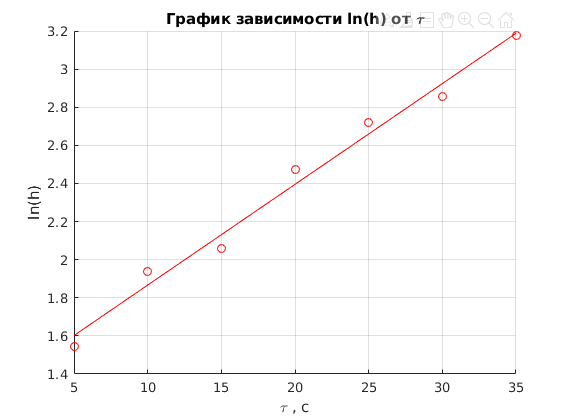

%{
x=[22.0 24.0 27.0 30.0 31.0 35.0 40.0];
y=[1.24 1.37 1.46 1.26 1.66 1.84 1.99];
% Найдем коэффициэнты полинома
a=polyfit(x,y,5),
%  Найдем значения полиномов в интервале от 20 до 40
x1=20:0.5:40;
y1=polyval(a,x1);
y0 = polyval(a,x); % расчет ф-ции в точках данных
% Погрешность аппроксимации по МНК
e=sum((y0-y).^2)/length(y)
%}



graph_1 = figure;
hold on;
    plot(OX1,  f1, 'r-');
    plot(OX1,  OY1 , 'ro');
hold off;

set   (graph_1, 'Visible', 'on'); 
ylabel('ln(h)');
xlabel('\tau , c');
title ('График зависимости ln(h) от \tau');
%legend("Нужная зависимость", 'Location','northwest');
grid on; 

saveas(graph_1, 'graph_1.png');

#### 6. Построение графика спектров всех звёзд

%graphStars = figure;

%hold on;
%for indxGraph = 1 : numStars
%    if speed(indxGraph) > 0
%        plot(lambda, spectra(:, indxGraph), ...
%             '-', ...
%             'Linewidth', 3);
%    else 
%        plot(lambda, spectra(:, indxGraph), ...
%             '--', ...
%             'Linewidth', 1); 
%    end
%end
%hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

%set   (graphStars, 'Visible', 'on'); 
%xlabel('Длина волны, нм');
%ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
%title ('Спектры звёзд');
%legend(starNames);
%grid on;
%saveas(graphStars, 'spectra.png');